# ASTE 577 Homework 5

## Problem 1

R = 8.315; %J/K-mol
M_CO2 = 2*15.999e-3 + 12.011e-3; %kg/mol
M_N2 = 2*14.007e-3; %kg/mol
M_O2 = 2*15.999e-3; %kg/mol
M_AR = 39.948e-3; %kg/mol

P = 101325; %Pa
T = 288; %K
g = 9.81; %m/s^2
M = 0.78084*M_N2 + 0.20946*M_O2 + 0.00934*M_AR; %kg/mol
H = R*T/(M*g); %m
rho0 = P*M/(R*T); %kg/m^3
earth = dictionary('H',H,'A',1/H,'rho0',rho0,'C_SG',1.7415e-4,'g',9.81,'R',6371e3);

P = 651.8; %Pa
T = (-120 - 32)*5/9 + 273.15; %K
g = 3.71; %m/s^2
M = 0.9532*M_CO2 + 0.027*M_N2 + 0.016*M_AR; %kg/mol
H = R*T/(M*g); %m
rho0 = P*M/(R*T); %kg/m^3
mars = dictionary('H',H,'A',1/H,'rho0',rho0,'C_SG',1.9027e-4);

stardust = dictionary('Ve',12.8e3,'FPA',-8.2,'Cd',1.8,'d',0.827,'me',45.8);
stardust('beta') = 4*stardust('me')/(stardust('Cd')*pi*stardust('d')^2);
stardust('Rn') = stardust('d')/4;
viking = dictionary('Ve',4.61e3,'FPA',-17,'Cd',1.65,'d',3.54,'me',980);
viking('beta') = 4*viking('me')/(viking('Cd')*pi*viking('d')^2);
viking('Rn') = viking('d')/4;

q = @(p, m) p('C_SG')*sqrt(-1/m('Rn')*m('beta')*p('A')*sind(m('FPA'))/3)*0.6055*m('Ve')^3;
stardust('q') = q(earth,stardust);
viking('q') = q(mars,viking);
stardust('q')*1e-3

ans = 7.9481e+03

viking('q')*1e-3

ans = 294.5630

#### (a) Peak heat flux: $q_{max,stardust} = 7,948.1 \frac{kW}{m^2}$ & $q_{max,viking}=294.6\frac{kW}{m^2}$

Q = @(p, m) p('C_SG')*sqrt(-m('beta')*pi/(m('Rn')*p('A')*sind(m('FPA'))))*m('Ve')^2;
stardust('Q') = Q(earth,stardust);
viking('Q') = Q(mars,viking);
stardust('Q')*1e-6

ans = 186.1261

viking('Q')*1e-6

ans = 10.8118

#### (b) Heat load per unit area: $Q_{stardust}=186.13\frac{MJ}{m^2}$ & $Q_{viking} = 10.81\frac{MJ}{m^2}$

Tw = @(m) (m('q')/(5.67e-8*0.8))^(1/4);
Tw(stardust)

ans = 3.6383e+03

Tw(viking)

ans = 1.5963e+03

#### (c) Equilibrium wall temp: $T_{w,stardust} = 3638.3 K$ & $T_{w,viking} = 1596.3 K$

v = @(m) 0.846*m('Ve');
v(stardust)*1e-3

ans = 10.8288

v(viking)*1e-3

ans = 3.9001

#### (d) Velocity at peak heating: $V_{e,stardust} = 10.83$ & $V_{e,viking} = 3.90$

stardust('Q')*pi/4*stardust('d')^2*1e-6

ans = 99.9789

viking('Q')*pi/4*viking('d')^2*1e-6

ans = 106.4129

#### (e) Total integrated heat load: $Q_{stardust}=99.98 MJ$ & $Q_{viking} = 106.41 MJ$

asind(sqrt(stardust('Cd')/2))

ans = 71.5651

#### (f) Stardust angle sphere cone is $71.57^{\circ}$

asind(sqrt(viking('Cd')/2))

ans = 65.2708

#### (g) Viking angle sphere cone is $65.27^{\circ}$

#### (h) The L/D ratio for each of these cases is 0 because they are ballistic entry.

## Problem 2

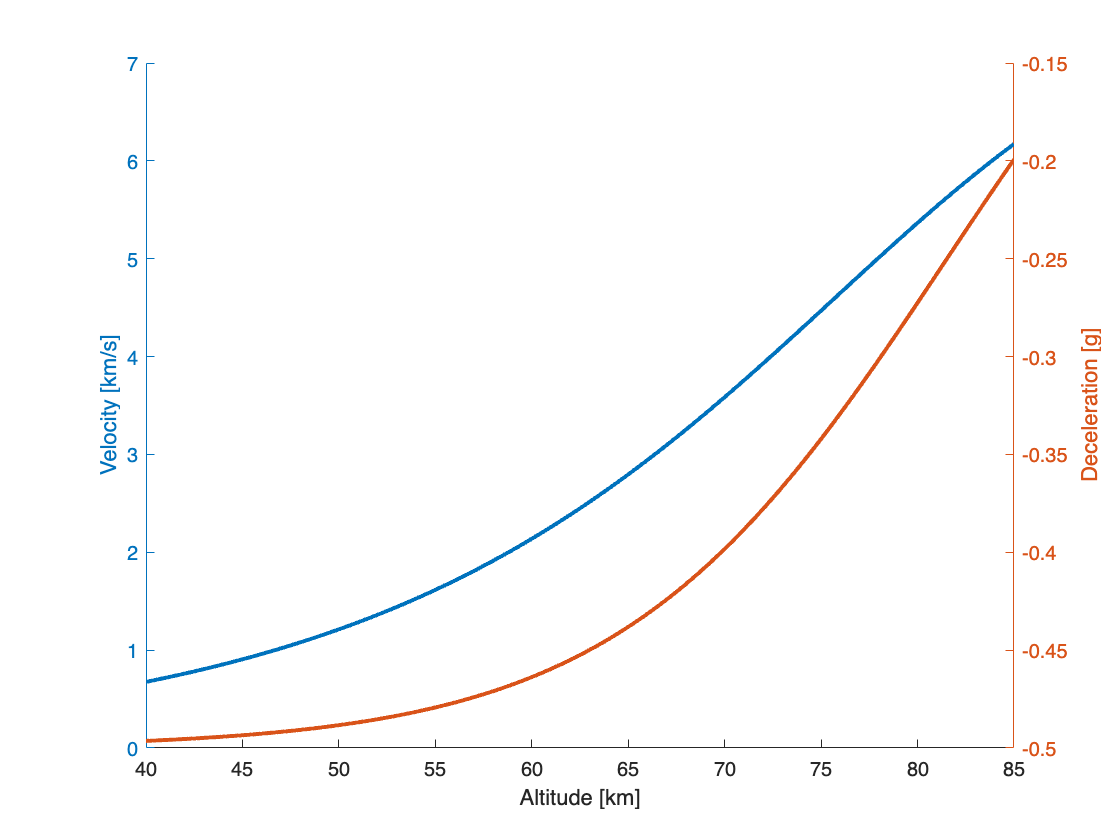

shuttle = dictionary('Ve',7.5e3,'he',85e3,'LD',2,'beta',500,'epsilon',0.8,'Rn',1,'m',94000,'S',250);
h = linspace(85e3,40e3,1000);
v = sqrt(earth('g').*(earth('R') + h)./(1 + earth('rho0').*exp(-earth('A').*h).*shuttle('LD')./(2.*shuttle('beta')).*(earth('R') + h)));
n = -(1 - v.^2./((earth('R') + h).*earth('g')))./shuttle('LD');

figure();
hold on
xlabel('Altitude [km]')
yyaxis left
ylabel('Velocity [km/s]')
plot(h/1000,v/1000,'LineWidth',2)
yyaxis right
ylabel('Deceleration [g]')
plot(h/1000,n,'LineWidth',2)
hold off

#### (a) See above graph

r = earth('R') + shuttle('he');
n_max = -1/shuttle('LD');
%h = 
s = -r/2*shuttle('LD')*log(1 - shuttle('Ve')^2/(r*earth('g')))*1e-3

s = 1.4143e+04

y = r/5.2*shuttle('LD')^2/sqrt(1 + 0.106*shuttle('LD')^2)*1e-3

y = 4.1616e+03

t = 0.5*sqrt(r/earth('g'))*shuttle('LD')*log((1 + shuttle('Ve')^2/(r*earth('g')))/(1 - shuttle('Ve')^2/(r*earth('g'))))/60

t = 38.2128

#### (b) $h_{n-max} = 40km$, $\Delta s = 14,143 km$, $\Delta y = 4,162 km$, & $\Delta t = 38.21 min$

Cd = shuttle('m')/(shuttle('beta')*shuttle('S'))

Cd = 0.7520

Cl = shuttle('LD')*Cd

Cl = 1.5040

#### (c) $C_D = 0.752$ & $C_L = 1.504$

shuttle('LD') = 2.5;
n_max = -1/shuttle('LD')

n_max = -0.4000

s = -r/2*shuttle('LD')*log(1 - shuttle('Ve')^2/(r*earth('g')))*1e-3

s = 1.7679e+04

y = r/5.2*shuttle('LD')^2/sqrt(1 + 0.106*shuttle('LD')^2)*1e-3

y = 6.0181e+03

#### (d) $n_{max} = -0.4 g$, $\Delta s = 17,679 km$, & $\Delta y = 6,018$

The L/D could be increased by changing the angle of attack.